clc; clear all; close all;

#### Generating Random Data to Transmit

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16; 
N_XData = 84;
Bits_per_set=64;
size_training_data = Bits_per_set*N_Training;
size_X = Bits_per_set*N_XData; %Size of data - 84 sets of 64 bits

range = [-1 1]; %List of wanted values
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

Create Data and Training Data

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

#### IDFT - Takes inverse discrete fourier tranform of data

Add Cyclic Prefix after each ifft


%IFFT of each individual set of 64
%Add prefix 
Len_CP = 16;
n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data
tx_data = [];

for x_time = 1:1:5
    Data_x_n = message(1 + 64*(x_time-1):x_time*64);
    Data_X_n = ifft(Data_x_n)
    cyclic_prefix = Data_X_n(length(Data_X_n)-Len_CP:end)
    
    
end

Data_X_n =   -0.1250 + 0.0000i
   0.0188 - 0.0196i
  -0.1518 + 0.0051i
  -0.1151 + 0.0785i
  -0.0960 - 0.0231i
   0.0341 - 0.0590i
   0.0606 - 0.1224i
   0.0175 + 0.1760i
  -0.1250 - 0.1067i
   0.0046 - 0.0221i


cyclic_prefix =   -0.1184 - 0.0449i
  -0.0625 + 0.0000i
  -0.0305 - 0.0689i
   0.0275 + 0.0464i
   0.0933 + 0.0936i
   0.0434 - 0.0199i
   0.2555 + 0.0543i
  -0.0352 + 0.0610i
   0.0046 + 0.0221i
  -0.1250 + 0.1067i


Data_X_n =   -0.0625 + 0.0000i
  -0.0521 - 0.0196i
   0.1224 + 0.1663i
   0.1658 + 0.0200i
   0.1485 + 0.0120i
   0.0902 - 0.0332i
  -0.0472 + 0.0161i
  -0.0520 - 0.0940i
   0.1859 - 0.0846i
  -0.0388 + 0.1635i


cyclic_prefix =    0.0357 - 0.0107i
   0.0938 + 0.0313i
  -0.2036 + 0.0458i
   0.0040 + 0.1119i
   0.1182 - 0.2739i
  -0.0452 - 0.0289i
   0.0869 - 0.0020i
   0.0300 + 0.1687i
  -0.0388 - 0.1635i
   0.1859 + 0.0846i


Data_X_n =    0.0625 + 0.0000i
  -0.0068 - 0.0433i
  -0.1293 + 0.0367i
   0.1010 - 0.0656i
  -0.0482 + 0.1807i
  -0.0519 + 0.1362i
   0.0173 + 0.0627i
  -0.0427 - 0.0255i
  -0.0183 + 0.0000i
  -0.1167 + 0.0134i


cyclic_prefix =   -0.1629 + 0.0896i
   0.0625 + 0.0625i
  -0.0627 + 0.1630i
  -0.0156 + 0.1638i
  -0.0399 - 0.0283i
  -0.0721 - 0.0605i
   0.0379 - 0.0883i
   0.1352 + 0.1031i
  -0.1167 - 0.0134i
  -0.0183 + 0.0000i


Data_X_n =   -0.0938 + 0.0000i
   0.1260 + 0.0430i
  -0.0010 + 0.0987i
   0.0832 + 0.0606i
  -0.0050 - 0.0255i
   0.0046 + 0.1644i
  -0.0838 - 0.2331i
  -0.0031 - 0.0487i
   0.1288 + 0.0404i
  -0.0044 - 0.0321i


cyclic_prefix =    0.0316 + 0.1056i
   0.0625 + 0.0313i
   0.0953 - 0.0213i
   0.1592 + 0.0707i
   0.0921 - 0.0398i
  -0.0697 - 0.0392i
   0.0774 - 0.1228i
   0.0902 - 0.0705i
  -0.0044 + 0.0321i
   0.1288 - 0.0404i


Data_X_n =   -0.0938 + 0.0000i
   0.0621 + 0.0708i
  -0.1403 - 0.1608i
   0.0465 + 0.1140i
   0.0669 + 0.0092i
  -0.0834 - 0.0261i
  -0.1336 - 0.0133i
  -0.0111 - 0.0348i
   0.1509 + 0.0754i
  -0.1213 - 0.0204i


cyclic_prefix =    0.1322 - 0.0035i
  -0.1563 + 0.0625i
  -0.0104 - 0.0077i
   0.0870 - 0.0002i
  -0.0262 + 0.0976i
   0.0773 + 0.0533i
  -0.0024 + 0.0598i
  -0.2008 + 0.0719i
  -0.1213 + 0.0204i
   0.1509 - 0.0754i



x_m = ifft(message); %Turns data points into impulses

#### Adding cyclic prefix



%Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix = x_m(49: 64);                  % Determines index of first cyclic prefix - 16 bits
tx_data(1:16) = cycPrefix;                % Initializes array that will hold data w/ prefix
tx_data(17:80) = x_m(1: 64);             % Loads first set of data  -  64 bits

%Index the Remaining Data
for R = 2:1:n_data  % Adds cyclic prefixes
    cycPrefix = x_m(64*(R-1)+ 48+1: 64*(R));
    tx_data(1 + 80*(R-1): 16*R + 64*(R-1)) = cycPrefix;
    Post_chunk =  x_m(64*(R-1)+1: 64*(R));
    tx_data(1 + 16*R + 64*(R-1) : 16*R + 64*R) = Post_chunk;
end
tx_data = transpose(tx_data)

tx_data =   -0.0193 + 0.0001i
  -0.0149 - 0.0120i
  -0.0024 + 0.0113i
  -0.0214 + 0.0098i
  -0.0035 + 0.0090i
  -0.0063 + 0.0061i
  -0.0015 + 0.0022i
  -0.0118 + 0.0056i
  -0.0004 - 0.0168i
   0.0019 + 0.0006i


#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel((tx_data));

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift1_train = lag1(Index); %Should be 9

%Remove Extra Data
rx_data = rx_data(shift1_train:shift1_train+length(tx_data)-1); %Should be 8000 bits

Estimate Channel: Estimating channel for each set of 64 bits using the Training Data

H = zeros(64,1);

%Obtain Training Data
Size_PC = 16;
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_set; %1280 Bits
Training_data_xm= rx_data(1:Size_Training_PC)

Training_data_xm =    0.0037 + 0.0002i
  -0.0152 + 0.0018i
  -0.0190 - 0.0131i
   0.0018 + 0.0051i
  -0.0198 + 0.0129i
  -0.0080 + 0.0061i
  -0.0021 + 0.0087i
  -0.0034 + 0.0004i
  -0.0083 + 0.0094i
  -0.0055 - 0.0143i



for G = 1:1:64  
    Data_N = Training_data_xm(G:64:end);
    Channel_estimate = Data_N./message(G);
    H(G) = mean(Channel_estimate);
end

Decode

Y_m = zeros(length(message),1);

for Z = 1:1:n_data
    X_est = fftshift(fft(rx_data(1 + 64*(Z-1):64*Z)));
    X_est=X_est./H;
    Y_m(1 + 64*(Z-1):64*Z) = X_est;
end

Plot X_est

Norm_ret = real(Y_m) ./ abs(real(Y_m))

Norm_ret =     -1
     1
    -1
     1
     1
     1
     1
    -1
     1
     1


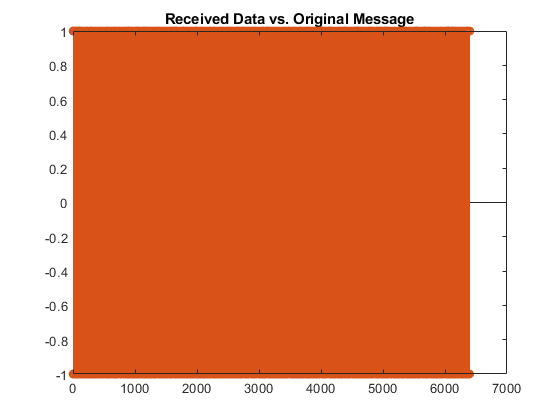


figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Error = abs(sum(diff)/(length(diff))) *100

Error = 50.4063

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

% H_k = zeros(100,1); %Empty vector to put transfer function values
% 
% for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
% end
% figure;
% stem(real(H_k));
% hold on
% title('Transfer Functions of Data');
% hold off
% 

Estimation of Noise

% est_noise = var(noise_thru_channel)
% 
% for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
%     w = ((conj(H_k(Z))));
%     Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
%     Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
% end


Estimate Channel Impulse Response

% Alpha_z = zeros(640,1);
% Impulse = ones(1,1);
% Beta_z = zeros(640,1);
% 
% Impulse_signal = [Alpha_z ; Impulse ; Beta_z]
% impulseresponse = nonflat_channel(Impulse_signal)
% impulseresponse = impulseresponse(649:660)
% figure;
% stem(impulseresponse,'*')
% hold on
% title('Impulse Response of System')
% xlabel('Time (s)');
% ylabel('Amplitude');
% ylim([-.3,1]);
% hold off

Circular Convolution

% rx_conv = conv(impulseresponse, rx_data)
% stem(rx_conv)

Realign

% % Determine Lag in Data
% [y1x1,lag1] = xcorr(rx_conv, rx_data); 
% [~, Index] = max(abs(y1x1));
% shift2 = lag1(Index)
% %Comes out to be 9
% 
% %Cut Data from Lag
% rx_data = rx_data(shift2:end);